clc
clear all


%%

j_first=[90;60;-120];
j4 = 360 - j_first(2,1) - j_first(3,1);
j=[j_first(1,1) j_first(2,1) j_first(3,1) j4;2 0 0 0;0 10 10 2;90 0 0 0];

**DHkine**


%collum 1=joint angle, 2=joint offset, 3=link lenght, 4=twist angle
T01=DHmatrix(j(1,1),j(2,1),j(3,1),j(4,1));
T12=DHmatrix(j(1,2),j(2,2),j(3,2),j(4,2));
T23=DHmatrix(j(1,3),j(2,3),j(3,3),j(4,3));
T34=DHmatrix(j(1,4),j(2,4),j(3,4),j(4,4));

T02=T01*T12;
T03=T02*T23;
T04=T03*T34;
FK=[T01 T02 T03 T04];
%FK=[T01 T02 T03 T04;T01 T12 T23 T34];


**XYZKine**

%%%%Huong cua EndEffector trong khong gian%%%%%
Q1=[0 FK(1,4) FK(1,8) FK(1,12) FK(1,16)];
Q2=[0 FK(2,4) FK(2,8) FK(2,12) FK(2,16)];
Q3=[0 FK(3,4) FK(3,8) FK(3,12) FK(3,16)];
Q=[Q1;Q2;Q3];

**Plot3: **

**Tạo thành điểm base (Q1[0];Q2[0];Q3[0])**

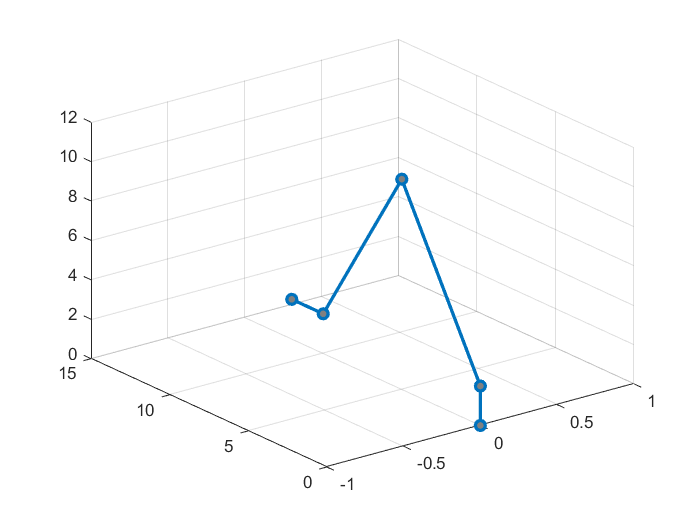

plot3(Q(1,:),Q(2,:),Q(3,:),'-o','LineWidth',2,'MarkerSize',6,'MarkerFaceColor',[0.5,0.5,0.5]);grid on;

**Calculate Q1 array**

Q(1,:)

ans =      0     0     0     0     0


**Calculate Q2 array**

Q(2,:)

ans =      0     0     5    10    12


**learn Plot3**

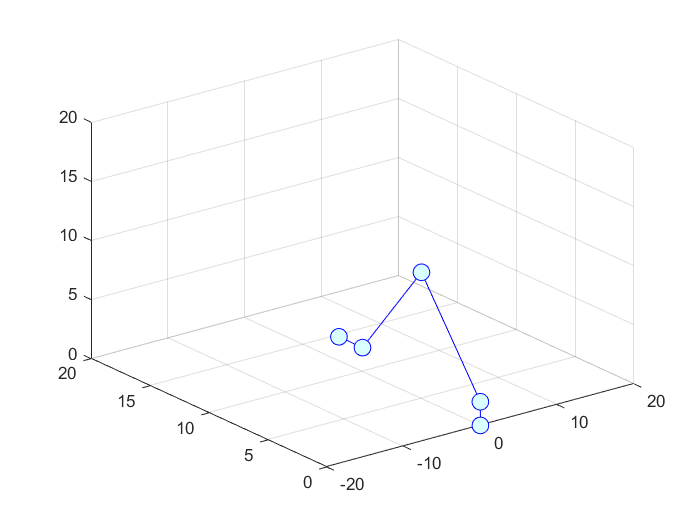

% t = 0:pi/20:10*pi;
% Q1 = [0	 0	0	0	0]
% Q2 = [0	0	0	0	0]
% Q3 = [0	0	0	0	0]
plot3(Q1,Q2,Q3,'-o','Color','b','MarkerSize',10,'MarkerFaceColor','#D9FFFF');grid on;
axis([-20 20 0 20 0 20]);
h = rotate3d;

h.Enable = 'off';

**Test các hàm GUIDE**

val2=str2num(get(handles.text2,'String'));

Unable to resolve the name handles.text2.

val3=str2num(get(handles.text3,'String'));
val1 = get(hObject,'Value') ;